# **Downsampling a Point Cloud to Facilitate its Analysis in Lidar Viewer**

Author: Avalon Royer

Student in Geography & Urban Planning at Paris-Cité University

Point clouds from Lidar databases tend to be large files, and during analysis using the Lidar Viewer application implemented in MATLAB, it often encounters difficulties in representing such large data sets, causing lag and crashes. Therefore, it is necessary to manually reduce the density of point clouds to lighten data processing.

The purpose of this livescript is to provide a simple, quick, and effective method to perform this operation, simplifying the point cloud by reducing the number of points it contains, thus making data manipulation much easier in dedicated applications.

**WARNING : **

1) The laz file is too large for GitHub so in Git Bash, execute `git lfs install`, then `git lfs pull` to download it.

2) Image Processing Toolbox, Lidar Toolbox and Computer Vision Toolbox are required.

**Reading and Displaying the Initial Point Cloud**

To obtain a file containing a point cloud, you can visit the following URL and select the area for which you wish to retrieve the point cloud: [https://geoservices.ign.fr/catalogue](https://geoservices.ign.fr/catalogue)

The `lasFileReader` function creates an object to read data from an LAS or LAZ file. In this case, the file is selected with a dialog (the LAZ file example couldn't be stored in GitHub because of the 100 MB limitation on file storage).

Then, the `readPointCloud` function uses the `lasFileReader` object to read the point cloud data from the file. It returns a `pointCloud` object that contains the point data, including their positions and possibly other attributes like color or intensity.

Finally, the `pcshow` function displays a 3D point cloud in a MATLAB figure. It uses the data from the `pointCloud` object to visualize the points in 3D space. Here, the points from the point cloud stored in `ptCloud` are displayed.

filefullpath = "";
[~,filename,fileext] = fileparts(filefullpath);
lasReader = lasFileReader(filename+fileext);

Error using lasFileReader (line 109)
Invalid argument at position 1. Value must be text with one or more characters.


ptCloud = readPointCloud(lasReader);

**Choice of Downsampling**

The first line assigns a percentage value to a function named `percentage`, which determines the proportion of points to retain in the simplified point cloud. For example, if you assign a value of `0.005`, it means that only 0.5% of the original points will be kept after downsampling.

For the second line, `pcdownsample(ptCloud, 'random', percentage, PreserveStructure=true);`:

- `ptCloud`: This is the `pointCloud` object that contains the original point cloud data.

- `'random'`: This option indicates that the downsampling method is random. It means points are randomly selected based on the percentage specified in the previous line.

- `percentage`: This parameter represents the percentage of points to retain.

- `PreserveStructure=true`: This option specifies that the organized structure of the point cloud should be preserved after downsampling. Thus, unselected points will be replaced with NaN values, and their corresponding colors will be set to `[0 0 0]` (black).

percentage = 0.006;
ptCloudDownsampled = pcdownsample(ptCloud,'random',percentage,PreserveStructure=true);

**Displaying the Result**

At this stage, we now want to see the result of the downsampling, which we do using `pcshow`.

We can also save it to the computer in a `.fig` format after displaying it in a separate window (*Open in figure window > Save as*).

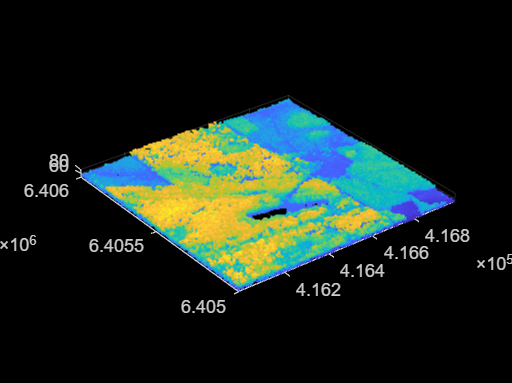

% this step can take a long time (3-30 seconds)

pcshow(ptCloudDownsampled)

**Import from Lidar Viewer**

To import the new point cloud into the Lidar Viewer application from the workspace, simply follow this path after opening the application: `Import > From Workspace > PtCloudsampled`.

Once this is done, the application will load your new simplified point cloud, and you will be able to perform the desired manipulations.

## Sources

Where to find point clouds : *https://geoservices.ign.fr/catalogue*